#  Initialization

clear
close all
clc

# Parameters

This Project focus on Fixed Pilot Length.

M       = 128;                      % Num of Antenna in BS
Ma      = 32;                       % Num of Selected Antenna
Mb      = M - Ma;                   % Num of Channel that should be Estimated
K       = 20;                       % Num of Users
L       = 10;                       % Num of MultiPath
N       = 5000;                     % Num of Realization
T_ch    = 200;                      % Coherence interval
T       = 40;                       % Lenght of Pilot Sequence
SNR_dB  = (-2:2:42);                % SNR in dB
SNR     = 10.^((-1)*(SNR_dB/10));   % SNR - Real Value
Var_Ch  = [0.01, 1, 4, 9, 16];      % Variance of Channel
Eps     = 0.001;                    % Epsilon
Ant_Set = 1:M;                      % Antenna Set

# Main Body

Fixed Pilot Length

tic

% O  ~> Orthogonal Pilot Sequence
% No ~> Non-Orthogonal Pilot Sequence
for z=1:length(Var_Ch)
    
    NMSE_Tot_O   = zeros(1,length(SNR));
    NMSE_Tot_No  = zeros(1,length(SNR));
    Ho_hat_Rate  = zeros(K,M);
    HNo_hat_Rate = zeros(K,M);
    Rate_O       = zeros(1,length(SNR));
    Rate_No      = zeros(1,length(SNR));
    
    for s=1:length(SNR)
        
        disp(' ')
        disp(['Var_Ch : ',num2str(Var_Ch(z)),'   SNR : ',num2str(SNR_dB(s))])
        disp(' ')
        Sum_O   = 0;
        Sum_No  = 0;
        NMSE_O  = zeros(1,N);
        NMSE_No = zeros(1,N);
        
        for n=1:N
            if rem(n,1000) == 0
                disp(['    N : ',num2str(n)])
            end
            % ---------------------------
            %       First Initialize
            Y_O       = zeros(1,T,K);
            Y_No      = zeros(1,T,K);
            % ---------------------------
            H_O       = zeros(1,Ma,K);
            H_No      = zeros(1,Ma,K);
            % ---------------------------
            HI_O      = zeros(L,Ma + 1,K);
            HI_No     = zeros(L,Ma + 1,K);
            % ---------------------------
            Ki_O      = zeros(Ma + 1,Mb,K);
            Ki_No     = zeros(Ma + 1,Mb,K);
            % ---------------------------
            h_b_O     = zeros(1,Mb,K);
            h_b_No    = zeros(1,Mb,K);
            % ---------------------------
            PiCh_O    = zeros(1,T,K);
            PiCh_No   = zeros(1,T,K);
            % ---------------------------
            HA_O_hat  = zeros(1,Ma,K);
            HA_No_hat = zeros(1,Ma,K);
            % ---------------------------
            log_2o    = zeros(1,K);
            log_2no   = zeros(1,K);
            % ---------------------------
            Dist           = Var_Ch(z) * rand(1,K);                     % Distance of Users from BS
            [Set_A,Set_B]  = Set_a(Ant_Set,M,Ma);                       % Selected Antenna
            [Ch,Ch_A,Ch_B] = Rayleigh(L,K,M,Ma,Set_A,Set_B,Dist);       % Total & Selected Channel
            
            P_O    = Pilot(Ma,T,K);                                     % Orthogonal Pilot Sequence
            P_No   = 2*randi([0 1],Ma,T,K) - 1;                         % Non Orthogonal Pilot Sequence
            
            P_OH   = Hermit(P_O,K);                                     % Pilot Hermitian
            P_No_H = Hermit(P_No,K);
            
            for k=1:K
                
                % Output of Channel
                PiCh_O(1,:,k)  = Ch_A(1,:,k)*P_O(:,:,k);
                PiCh_No(1,:,k) = Ch_A(1,:,k)*P_No(:,:,k);
                
                % Add Noise & Receiver Input
                Noise_O     = sqrt(SNR(s)) * randn(1,T);
                Noise_No    = sqrt(SNR(s)) * randn(1,T);
                
                Y_O(1,:,k)  = PiCh_O(1,:,k)  + Noise_O;
                Y_No(1,:,k) = PiCh_No(1,:,k) + Noise_No;
                
                % Downlink Estimation of Orthogonal & Non_Orthogonal Pilot
                H_O(1,:,k)  = (Y_O(1,:,k)*P_OH(:,:,k))/T;
                H_No(1,:,k) = (Y_No(1,:,k)*P_No_H(:,:,k))/(P_No(:,:,k)*P_No_H(:,:,k));
                
                % FeedBack CSI by adding a Random Value "delta"
                % Var(delta) = sqrt(epsilon)*Var(H_check_A)
                Del_O  = (sqrt(Eps)*var(H_O(1,:,k)))  * randn(1,Ma,K);
                Del_No = (sqrt(Eps)*var(H_No(1,:,k))) * randn(1,Ma,K);
                
                HA_O_hat(1,:,k)  = H_O(1,:,k)  + Del_O(:,:,k);
                HA_No_hat(1,:,k) = H_No(1,:,k) + Del_No(:,:,k);
                
                % HI   = [Re(Ch_A),1]
                HI_O(:,:,k)  = [Ch_A(:,:,k),ones(L,1)];
                HI_No(:,:,k) = [Ch_A(:,:,k),ones(L,1)];
                
                % Regression Coefficient
                Ki_O(:,:,k)  = pinv(transpose(HI_O(:,:,k)) *HI_O(:,:,k))  * transpose(HI_O(:,:,k))  * Ch_B(:,:,k);
                Ki_No(:,:,k) = pinv(transpose(HI_No(:,:,k))*HI_No(:,:,k)) * transpose(HI_No(:,:,k)) * Ch_B(:,:,k);
                
                % Estimated Channel
                h_b_O(:,:,k)  = [H_O(1,:,k),1]*Ki_O(:,:,k);
                h_b_No(:,:,k) = [H_No(1,:,k),1]*Ki_No(:,:,k);
                
            end
            
            % Combination Estimated and FeedBack Channel
            H_Es_O  = ChCombine(HA_O_hat, h_b_O, M,K,Set_A,Set_B);   % Estimated for Orthogonal Mode, hat{H_O}
            H_Es_No = ChCombine(HA_No_hat,h_b_No,M,K,Set_A,Set_B);   % Estimated for Non-Orthogonal Mode, hat{H_No}
            Ch_Real = Ch(1,:,:);                                     % Real Values of Channel, H
            
            % Tilda{H} = H - hat{H}
            H_til_O  = Ch_Real - H_Es_O;
            H_til_No = Ch_Real - H_Es_No;
            
            for i=1:K
                Ho_hat_Rate(i,:)  = H_Es_O(1,:,i);        % H_hat Matrix for Estimating Rate (Orthogonal)
                HNo_hat_Rate(i,:) = H_Es_No(1,:,i);       % H_hat Matrix for Estimating Rate (Non-Orthogonal)
            end
            W_O  = transpose(Ho_hat_Rate) /(Ho_hat_Rate *transpose(Ho_hat_Rate));
            W_No = transpose(HNo_hat_Rate)/(HNo_hat_Rate*transpose(HNo_hat_Rate));
            
            % log2(1 + SINR)
            for j=1:K
                log_2o(1, j) = log2(1 + SINR(Ch_Real,H_Es_O,W_O,  SNR(s),j));
                log_2no(1,j) = log2(1 + SINR(Ch_Real,H_Es_No,W_No,SNR(s),j));
            end
            Sum_O  = Sum_O  + sum(log_2o);
            Sum_No = Sum_No + sum(log_2no);
            
        end                                 % End of for on Itterations
        
        % ~> sum (log2)/N
        Rate_O (1,s) = (1 - (T/T_ch)) * (Sum_O  / N);          % Rate of Orthogonal
        Rate_No(1,s) = (1 - (T/T_ch)) * (Sum_No / N);          % Rate of Non-Orthogonal
        
    end                                     % End of for on SNRs
    

Var_Ch : 0.01   SNR : -2


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 0.01   SNR : 0


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 0.01   SNR : 2


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 0.01   SNR : 4


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 0.01   SNR : 6


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 0.01   SNR : 8


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 0.01   SNR : 10


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 0.01   SNR : 12


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 0.01   SNR : 14


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 0.01   SNR : 16


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 0.01   SNR : 18


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 0.01   SNR : 20


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 0.01   SNR : 22


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 0.01   SNR : 24


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 0.01   SNR : 26


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 0.01   SNR : 28


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 0.01   SNR : 30


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 0.01   SNR : 32


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 0.01   SNR : 34


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 0.01   SNR : 36


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 0.01   SNR : 38


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 0.01   SNR : 40


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 0.01   SNR : 42


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 1   SNR : -2


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 1   SNR : 0


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 1   SNR : 2


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 1   SNR : 4


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 1   SNR : 6


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 1   SNR : 8


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 1   SNR : 10


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 1   SNR : 12


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 1   SNR : 14


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 1   SNR : 16


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 1   SNR : 18


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 1   SNR : 20


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 1   SNR : 22


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 1   SNR : 24


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 1   SNR : 26


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 1   SNR : 28


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 1   SNR : 30


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 1   SNR : 32


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 1   SNR : 34


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 1   SNR : 36


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 1   SNR : 38


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 1   SNR : 40


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 1   SNR : 42


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 4   SNR : -2


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 4   SNR : 0


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 4   SNR : 2


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 4   SNR : 4


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 4   SNR : 6


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 4   SNR : 8


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 4   SNR : 10


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 4   SNR : 12


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 4   SNR : 14


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 4   SNR : 16


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 4   SNR : 18


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 4   SNR : 20


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 4   SNR : 22


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 4   SNR : 24


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 4   SNR : 26


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 4   SNR : 28


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 4   SNR : 30


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 4   SNR : 32


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 4   SNR : 34


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 4   SNR : 36


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 4   SNR : 38


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 4   SNR : 40


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 4   SNR : 42


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 9   SNR : -2


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 9   SNR : 0


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 9   SNR : 2


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 9   SNR : 4


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 9   SNR : 6


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 9   SNR : 8


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 9   SNR : 10


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 9   SNR : 12


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 9   SNR : 14


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 9   SNR : 16


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 9   SNR : 18


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 9   SNR : 20


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 9   SNR : 22


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 9   SNR : 24


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 9   SNR : 26


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 9   SNR : 28


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 9   SNR : 30


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 9   SNR : 32


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 9   SNR : 34


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 9   SNR : 36


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 9   SNR : 38


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 9   SNR : 40


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 9   SNR : 42


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 16   SNR : -2


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 16   SNR : 0


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 16   SNR : 2


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 16   SNR : 4


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 16   SNR : 6


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 16   SNR : 8


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 16   SNR : 10


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 16   SNR : 12


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 16   SNR : 14


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 16   SNR : 16


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 16   SNR : 18


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 16   SNR : 20


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 16   SNR : 22


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 16   SNR : 24


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 16   SNR : 26


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 16   SNR : 28


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 16   SNR : 30


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 16   SNR : 32


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 16   SNR : 34


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 16   SNR : 36


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 16   SNR : 38


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 16   SNR : 40


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


Var_Ch : 16   SNR : 42


    N : 1000
    N : 2000
    N : 3000
    N : 4000
    N : 5000


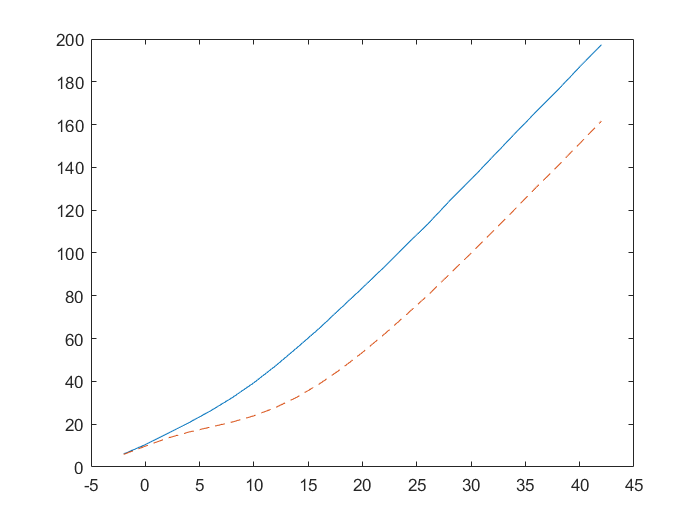

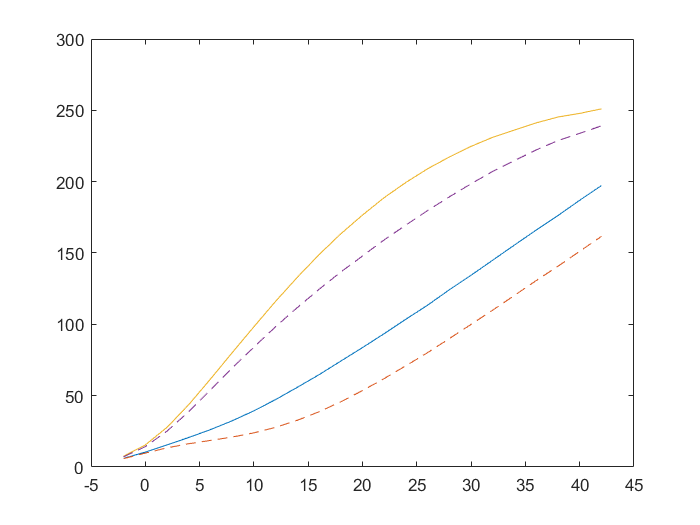

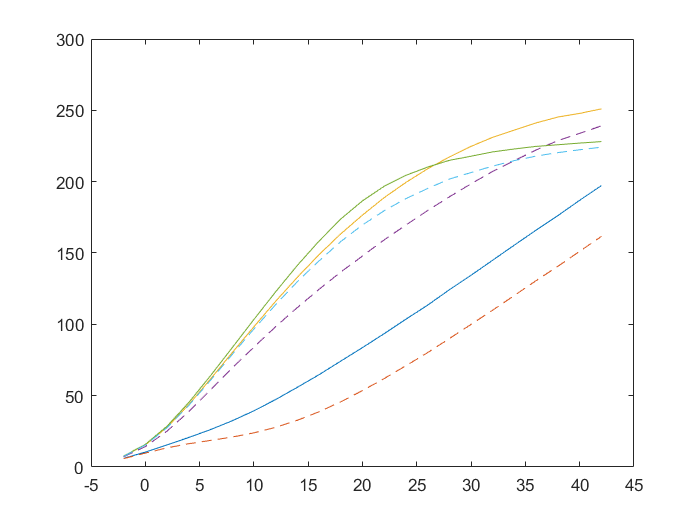

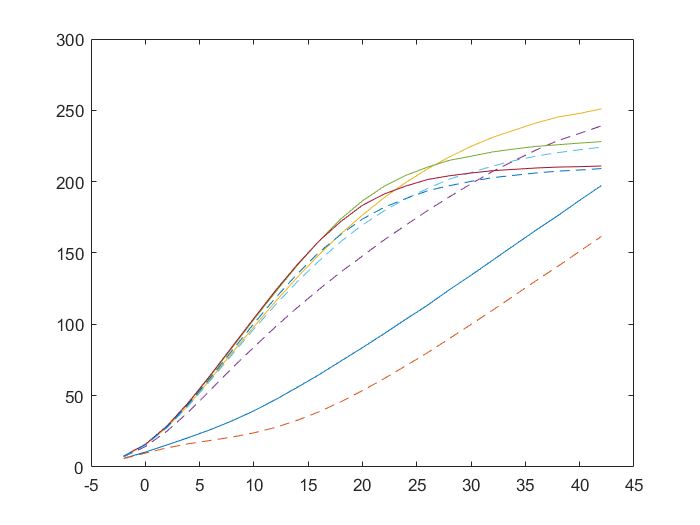

    
    % figure
    plot(SNR_dB,Rate_O,SNR_dB,Rate_No,'--')
    hold on

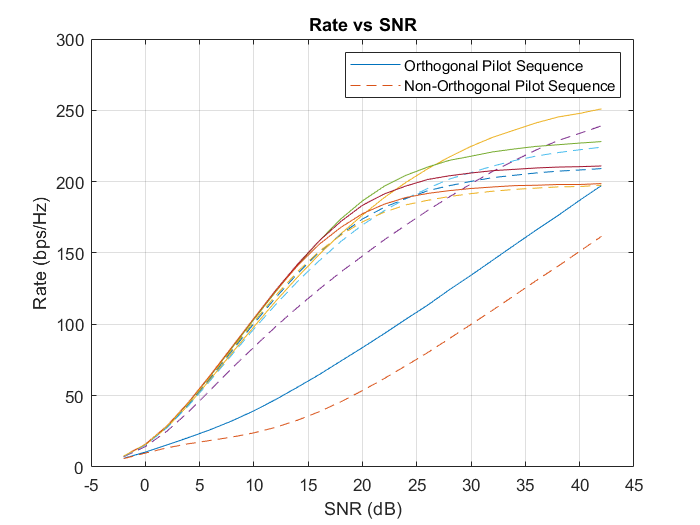

Elapsed time is 22490.703734 seconds.


    
end

grid on
title('Rate vs SNR')
xlabel('SNR (dB)')
ylabel('Rate (bps/Hz)')
legend('Orthogonal Pilot Sequence','Non-Orthogonal Pilot Sequence')

toc



